# Tópicos Especiais em Estatística Aplicada – 2023-2

## EPC 6 - João Gabriel Santos Custodio

Sejam as 2000 amostras fornecidas das variáveis aleatórias Y e X do arquivo epc6.mat ou csv. O intervalo 1 vai da amostra 1 até a amostra 1000. O intervalo 2 vai da amostra 1001 até a amostra 2000. A relação entre X e Y muda de um intervalo para outro. 

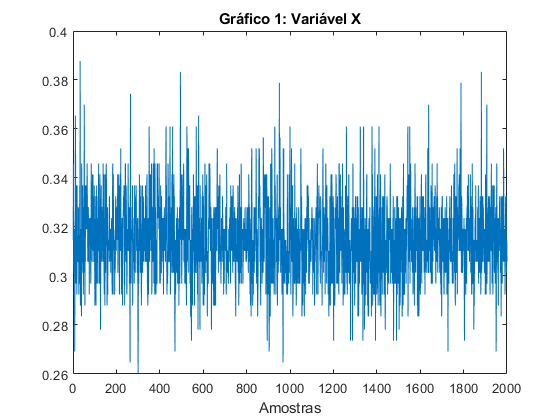

load('epc6.mat')
eixo_x = linspace(1,2000,2000);
figure
plot(eixo_x,x)
title("Gráfico 1: Variável X")
xlabel("Amostras")

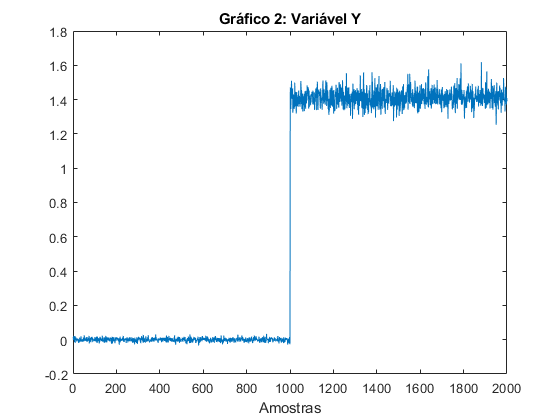

figure
plot(eixo_x,y)
title("Gráfico 2: Variável Y")
xlabel("Amostras")

1) **Teste de hipótese de correlação.**

Faça o teste de hipótese de correlação entre X e Y nos dois intervalos, mostrando o pvalor do teste de hipótese de que há ou não correlação entre elas. Ilustre plotando o gráfico de dispersão. Repita o teste algumas vezes usando apenas 10 amostras, e comente. Qual a hipótese nula?

Resposta:

Primeiramente, deve-se analisar os gráficos de dispersão nos dois intervalos:

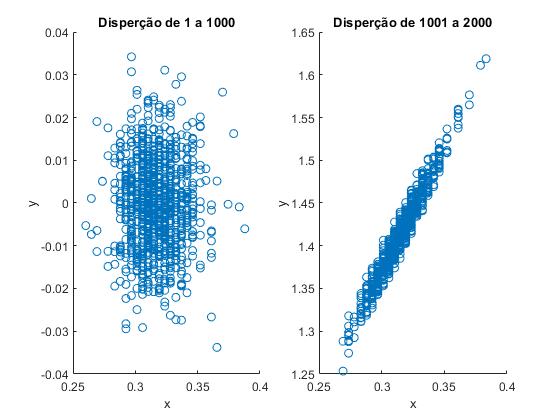

figure
subplot(1,2,1)
scatter(x(1:1000),y(1:1000));
title("Disperção de 1 a 1000")
ylabel("y")
xlabel("x")
subplot(1,2,2)
scatter(x(1001:2000),y(1001:2000));
title("Disperção de 1001 a 2000")
ylabel("y")
xlabel("x") 

Teste de hipótese utilizando a função corr()

[rho1,pval1] = corr(x(1:1000),y(1:1000));
display("O intervalo de 1 a 1000 tem uma correlção de confinça com p-valor de " + pval1) 

    "O intervalo de 1 a 1000 tem uma correlção de confinça com p-valor de 0.61322"




[rho2,pval2] = corr(x(1001:2000),y(1001:2000));
display("O intervalo de 1 a 1000 tem uma correlção de confinça com p-valor de " + pval2) 

    "O intervalo de 1 a 1000 tem uma correlção de confinça com p-valor de 0"



Fica evidente que o segundo intervalo tem uma correlação muito mais confiável em relação ao primeiro, tal fato é verificado pelo gráfico de dispersão de 1001 a 2000 onde as amostras tendem a se relacionar com uma frequência maior do que o primeiro intervalo de 1 a 1000.

Repetindo o teste com 10 amostras:

pvalores1 = zeros(1,10);
pvalores2 = zeros(1,10);
teste_10_1 = randi([1 1000],10,1);
teste_10_2 = randi([1001 2000],10,1);
for i = 1:1:10
 inter1x = x(teste_10_1);
 inter1y = y(teste_10_1);
 inter2x = x(teste_10_2);
 inter2y = y(teste_10_2);
 [r1,pv1] = corr(inter1x,inter1y);
 [r2,pv2] = corr(inter2x,inter2y);

 pvalores1(i) = pv1;
 pvalores2(i) = pv2;
end
disp("Os p-valores de 10 amostras no primeiro intervalo são " )

Os p-valores de 10 amostras no primeiro intervalo são 


pvalores1

pvalores1 =     0.6833    0.6833    0.6833    0.6833    0.6833    0.6833    0.6833    0.6833    0.6833    0.6833



disp("Os p-valores segundo intervalo são")

Os p-valores segundo intervalo são


pvalores2

pvalores2 = 	1.0e+-5 *

    0.4685    0.4685    0.4685    0.4685    0.4685    0.4685    0.4685    0.4685    0.4685    0.4685


Observa-se que mesmo que o número de amostras tenha diminuído drásticamente o segundo teste apresenta a maior confiabilidade, isso fica evidente devido os valores de p-valor da ordem de 10^-6. Dessa forma, associando a ordem de grandeza dos valores de p-valor do segundo teste, a afirmação de que o segundo intervalo estar correlacionado é mais confiável do que o primeiro intervalo.

**2) Estimação dos parâmetros de modelos de regressão**

Selecione aleatoriamente 100 pares (x,y) de amostras e estime 100 vezes os parâmetros do modelo de regressão y = β0 + β1x. Use para isto o intervalo de dados em que X e Y estão correlacionadas. Compare o histograma de β0 e de β1 com suas funções de distribuição de probabilidade teóricas. 

Resposta:

X_corr = x(1001:2000);
Y_corr = y(1001:2000);
b0_vet = zeros(1,100);
b1_vet = zeros(1,100); 

for i = 1:1:100
 input_100_rnd = randi([1 1000],100,1);
 interx_100 = X_corr(input_100_rnd);
 intery_100 = Y_corr(input_100_rnd);

 b_i = regress(intery_100 ,[ones(size(interx_100)),interx_100]);
 b0_vet(i) = b_i(1);
 b1_vet(i) = b_i(2);
end

Cálculo e plotagem dos histogramas normalizados dos coeficientes e suas PDF's:

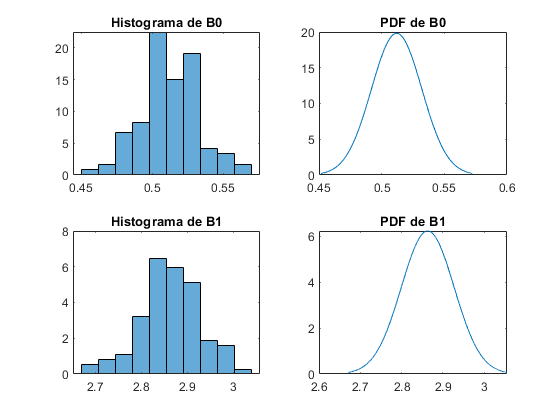

%cálculo PDFS

eixo_x_b0 = mean(b0_vet)-3*std(b0_vet):0.0001:mean(b0_vet)+3*std(b0_vet);
eixo_x_b1 = mean(b1_vet)-3*std(b1_vet):0.0001:mean(b1_vet)+3*std(b1_vet);
pdf_b0 = normpdf(eixo_x_b0,mean(b0_vet),std(b0_vet));
pdf_b1 = normpdf(eixo_x_b1,mean(b1_vet),std(b1_vet));

%plots

figure
subplot(2,2,1)
histogram(b0_vet,10,"Normalization","pdf")
title("Histograma de B0")

subplot(2,2,2)
plot(eixo_x_b0,pdf_b0)
title("PDF de B0")

subplot(2,2,3)
histogram(b1_vet,10,"Normalization","pdf")
title("Histograma de B1")

subplot(2,2,4)
plot(eixo_x_b1,pdf_b1)
title("PDF de B1")

Nota-se que a média da PDF de $\beta 1$está mais afastada da origem quando comparamos à média da PDF de $\beta 0,$isso indica que o segundo intervalo tem uma boa correlação entre os dados de x e y, haja vista que o coeficiente angular da regressão indicará um bom crescimento ou decrescimento linear.

**3) Teste de hipóteses em modelos de regressão**

Obtenha um modelo de regressão para o intervalo 1 de dados e outro modelo para o intervalo 2. Use o teste de hipótese sobre o parâmetro de inclinação β1 para verificar a existência de um modelo de regressão para cada intervalo. Para estimar os modelos, use 100 pares de amostras (x,y) selecionadas aleatoriamente nos intervalos. Ilustre o teste de hipótese com gráfico da pdf de β1, indicando nele a estatística de teste utilizada no teste de hipótese. 

Resposta:

X_ncorr = x(1:1000);
Y_ncorr = y(1:1000);
ind_100 = randi([1 1000],100,1);
X_nc_a = X_ncorr(ind_100);
Y_nc_a = Y_ncorr(ind_100);
X_c_a = X_corr(ind_100); 
Y_c_a = Y_corr(ind_100);
[b_nc,CI_nc, res_nc, rint_nc, stats_nc] = regress(Y_nc_a,[ones(100,1),X_nc_a]); [b_c,CI_c, res_c, rint_c,stats_c] = regress(Y_c_a,[ones(100,1),X_c_a]); 

Considerando o primeiro modelo de 1 a 1000 e o segundo modelo de 1001 a 2000:

display("O t B1 do primeiro modelo é "+b_nc(2)) 

    "O t B1 do primeiro modelo é 0.05562"




display("O t B1 do segundo modelo é "+b_c(2))

    "O t B1 do segundo modelo é 2.8636"




display("O coeficiente R2 do primeiro modelo é "+stats_nc(1))

    "O coeficiente R2 do primeiro modelo é 0.0090102"




display("O coeficiente R2 do segundo modelo é "+stats_c(1)) 

    "O coeficiente R2 do segundo modelo é 0.9464"



Através da análise dos valores dos coeficientes R² e B₁ em ambos os intervalos, novamente observamos evidências de ausência de correlação no primeiro intervalo, seguido por uma forte correlação dos dados no segundo intervalo.

O teste de hipótese, usado para determinar se há de fato correlação, envolve a rejeição da hipótese nula quando esta é formulada da seguinte maneira: Se a hipótese nula for verdadeira, isso indicaria a falta de correlação devido à inexistência de um coeficiente angular no modelo. Ao organizar as hipóteses do teste de forma mais clara:

- A hipótese nula é rejeitada quando se considera que não existe correlação, justamente devido à ausência de um coeficiente angular no modelo.

Para encontrarmos a estatística de teste T0 será seguido a equação abaixo: 

Cálculo de SSe e SSx para o cálculo de $\sigma^2$

SSe_nc = sum(res_nc.^2);
SSe_c = sum(res_c.^2); 
SSx_nc = 0;
SSx_c = 0;
for i = 1:1:100
 SSx_nc = SSx_nc + (X_nc_a(i) - mean(X_nc_a)).^2;
 SSx_c = SSx_c + (X_c_a(i) - mean(X_c_a)).^2;
end

rho_nc = SSe_nc/(98);
rho_c = SSe_c/(98);

Considerando $\beta_1$, podemos calcular T0: 

T0_nc = b_nc(2)/sqrt(rho_nc/SSx_nc) 

T0_nc = 0.9439

T0_c = b_c(2)/sqrt(rho_c/SSx_c)

T0_c = 41.5959

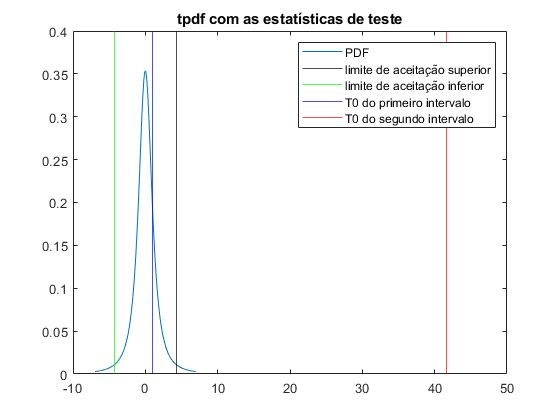

% Calculo e plot das PDF's
eixo_x_t = linspace(tinv(0.01, 2),tinv(0.99, 2),1000);
pdf_t = tpdf(eixo_x_t,2);
figure
plot(eixo_x_t,pdf_t)
title("tpdf com as estatísticas de teste")
hold on
xline(tinv((1 - 0.05/2), 2),'black')
xline(tinv((0.05/2), 2),'g')
xline(T0_nc,'b')
xline(T0_c,'r')
legend("PDF","limite de aceitação superior","limite de aceitação inferior","T0 do primeiro intervalo","T0 do segundo intervalo") 

Com base no documento PDF fornecido, ao considerar as informações disponíveis e a análise estatística, podemos chegar às seguintes conclusões:

No primeiro intervalo, a estatística de teste, encontra-se no centro do intervalo de confiança. Isso sugere que não há evidência estatística de correlação entre as variáveis x e y nesse intervalo.

No entanto, no segundo intervalo, observa-se que a estatística de teste T0 está consideravelmente distante da região de aceitação. Isso indica que a hipótese nula é rejeitada com segurança, o que sugere fortemente a presença de uma correlação substancial entre as variáveis no segundo intervalo. Em resumo, os dados fornecem evidências estatísticas claras de uma forte correlação entre as variáveis x e y nesse segundo intervalo.

**4) Análise dos resíduos**

Analise o resíduo dos dois modelos da atividade 3, calculando o coeficiente de regressão R 2 e verificando se as amostras de resíduo são independentes. Que conclusões se pode tirar sobre os dois modelos a partir desta análise? Resposta: 

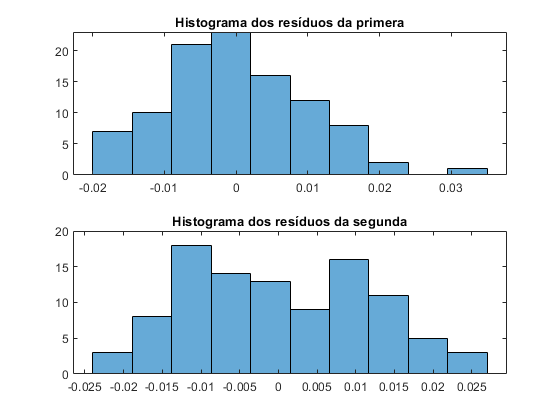

figure
subplot(2,1,1)
histogram(res_nc,10)
title("Histograma dos resíduos da primera")
subplot(2,1,2)
histogram(res_c,10)
title("Histograma dos resíduos da segunda") 

Analisando os histogramas dos resíduos, podemos afimar que ambos os modelos mostram que temos uma distribuição normal. 

Para calcular R² e SST:

SSt_nc = 0;
SSt_c = 0;
for i = 1:1:100
 SSt_nc = SSt_nc + (Y_nc_a(i) - mean(Y_nc_a)).^2;
 SSt_c = SSt_c + (Y_c_a(i) - mean(Y_c_a)).^2;
end

R² primeira parte:

R2_nc = 1 - SSe_nc/SSt_nc;
display("R2 para primeira parte dos dados é "+R2_nc) 

    "R2 para primeira parte dos dados é 0.0090102"



R² segunda parte:

R2_c = 1 - SSe_c/SSt_c;
display("R2 para segunda parte dos dados é "+R2_c) 

    "R2 para segunda parte dos dados é 0.9464"



Na segunda parte dos dados é notável a proximidade de R² à 1, provando a correlação dos dados. Tal evidencia não acontece para a primeira parte visto que o valor de R² é muito baixo.

Análise dos resíduos:

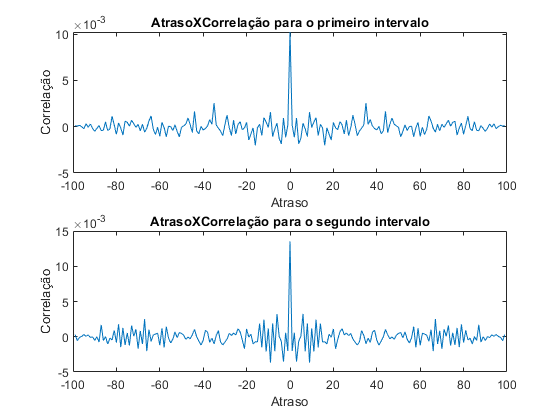

[c_nc,lags_nc] = xcorr(res_nc);
[c_c,lags_c] = xcorr(res_c);
figure
subplot(2,1,1)
plot(lags_nc,c_nc)
title("AtrasoXCorrelação para o primeiro intervalo")
xlabel("Atraso")
ylabel("Correlação")
subplot(2,1,2)
plot(lags_c,c_c)
title("AtrasoXCorrelação para o segundo intervalo")
xlabel("Atraso")
ylabel("Correlação") 

Nota-se que vemos uma relação de correlação somente quando o atraso é 0, portanto podemos afirmar que os resíduos são independentes.

**5) Previsão usando o modelo de regressão **

Use o modelo de regressão aprovado no teste de hipótese da atividade 3 para estimar valores futuros de y. Para isso, utilize 10 novos valores de x no intervalo [0,25, 0.35] e 10 novos valores no intervalo [0.35 0.50]. Esses valores são propostos, e não extraídos de X. Plote os 100 pares (x,y) usados para obter o modelo junto com os pares obtidos com os 20 valores estimados. Em outra figura, plote os 20 valores estimados junto com seu intervalo de confiança, explicando como esse intervalo pode ser reduzido.

Resposta:

Para a previsão, vamos considerar a seguinte equação abaixo:


$$Y=\beta_0 +\beta_1 x$$


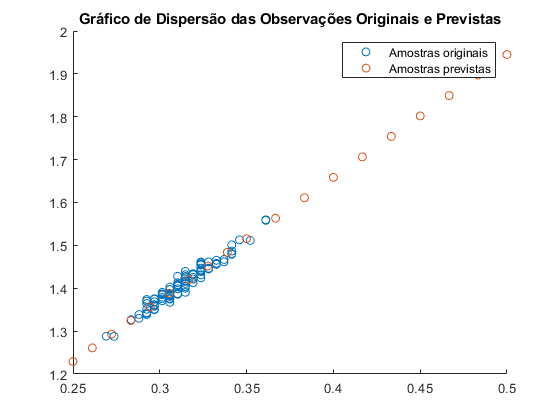

x_1 = linspace(0.25,0.35,10);
x_2 = linspace(0.35,0.50,10);
y_1 = b_c(1) + b_c(2)*x_1;
y_2 = b_c(1) + b_c(2)*x_2; 

% Calculo para o gráfico

y_0 = [y_1 y_2];
x_0 = [x_1 x_2];
figure
scatter(X_c_a,Y_c_a);
hold on
scatter(x_0,y_0);
title("Gráfico de Dispersão das Observações Originais e Previstas")
legend("Amostras originais","Amostras previstas") 

Nota-se que os intervalo das amostras originais estão contidas na previsão, portanto a previsão foi boa.

Agora, para determinar o intervalo de confiança, utiliza-se a equação abaixo. ($\hat{y} \;$são os valores presentes na concatenação dos vetores y1 e y2)

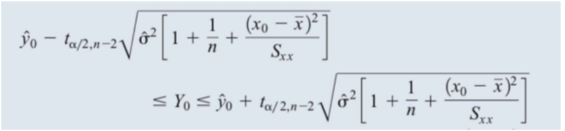

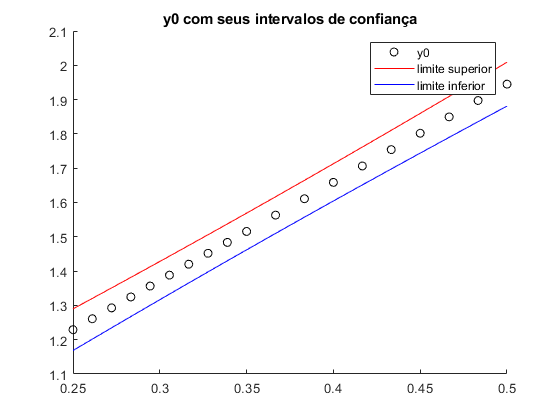

int_sup = zeros(20,1);
int_inf = zeros(20,1);
for i = 1:1:20
 int_sup(i) = y_0(i) + tinv((1 - 0.05/2), 2)*sqrt(rho_qd_c*(1 + 1/2 + (x_0(i)-mean(x_0))^2/SSx_c));
 int_inf(i) = y_0(i) - tinv((1 - 0.05/2), 2)*sqrt(rho_qd_c*(1 + 1/2 + (x_0(i)-mean(x_0))^2/SSx_c));
end

% Plotagem do gráfico

figure
scatter(x_0,y_0, 'black');
hold on
plot(x_0,int_sup, 'r')
plot(x_0,int_inf, 'b') 
title("y0 com seus intervalos de confiança")
legend("y0","limite superior","limite inferior") 

Dado que temos a equação que descreve os intervalos de confiança, para reduzir a largura desses intervalos, é necessário diminuir o valor da variância. Isso implica em reduzir a dispersão dos valores de Y em relação à sua média. Em outras palavras, estamos buscando reduzir a variabilidade na variável estimada. Uma abordagem para atingir esse objetivo envolve minimizar o erro na regressão.